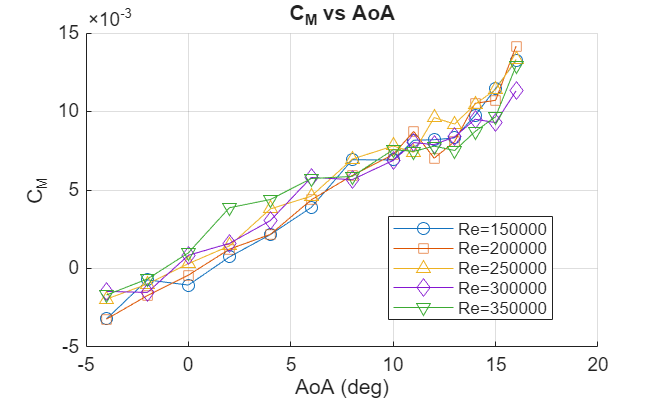

clearvars; close all;

% --- Load table T ---
fname = "\\wsl.localhost\Ubuntu-22.04\home\mteggeri\OpenFOAM\mteggeri-13\run\all_forceCoeffs_raw.dat";
if isfile(fname)
    opts = delimitedTextImportOptions("NumVariables",6);
    opts.Delimiter = {' ','\t'};
    opts.ConsecutiveDelimitersRule = "join";
    opts.VariableNames = {'Velocity','AoA','Iter','CM','CD','CL'};
    opts.VariableTypes = repmat("double",1,6);
    T = readtable(fname, opts);
else
    error('File not found. Load your data first.');
end

% --- Settings ---
wantedAoA = [-4,-2,0,2,4,6,8,10,11,12,13,14,15,16];
velocities = [15,20,25,30,35];
colors = lines(numel(velocities));
markers = {'o','s','^','d','v'};

% --- Create separate figures ---
figure(1); hold on; grid on;
title('C_M vs AoA'); xlabel('AoA (deg)'); ylabel('C_M');

figure(2); hold on; grid on;
title('C_D vs AoA'); xlabel('AoA (deg)'); ylabel('C_D');

figure(3); hold on; grid on;
title('C_L vs AoA'); xlabel('AoA (deg)'); ylabel('C_L');

% --- Plot per velocity ---
for k = 1:numel(velocities)
    v = velocities(k);
    Tf = T(T.Velocity==v & ismember(T.AoA, wantedAoA), :);
    if isempty(Tf), continue; end

    [AoA_sorted, si] = sort(Tf.AoA);
    CM = Tf.CM(si);
    CD = Tf.CD(si);
    CL = Tf.CL(si);

    m = markers{mod(k-1,numel(markers))+1};

    figure(1);
    plot(AoA_sorted, CM, 'Color',colors(k,:), 'Marker',m);

    figure(2);
    plot(AoA_sorted, CD, 'Color',colors(k,:), 'LineWidth', 1.2,'Marker',m);

    figure(3);
    plot(AoA_sorted, CL, 'Color',colors(k,:), 'LineWidth', 1.2, 'Marker',m);
end

% --- Legends ---
legendStrings = arrayfun(@(x)sprintf('V=%d',x), velocities, 'UniformOutput',false);

figure(1); legend(legendStrings, 'Location','best');
figure(2); legend(legendStrings, 'Location','best');
figure(3); legend(legendStrings, 'Location','best');
% map velocities to Re (example: Re = V * 10000)
Re = velocities * 10000;
legendStrings = arrayfun(@(r)sprintf('Re=%d', r), Re, 'UniformOutput', false);

figure(1); legend(legendStrings, 'Location','best');

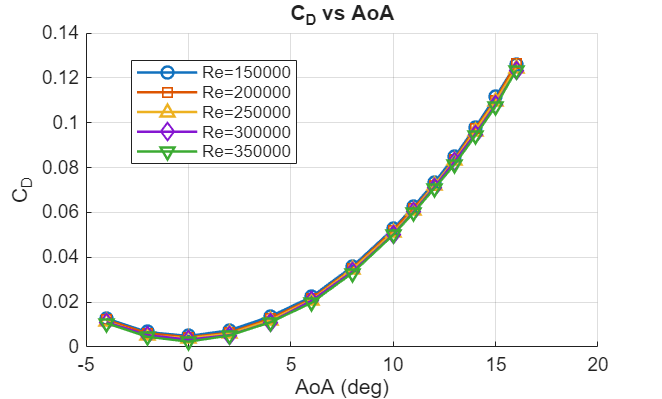

figure(2); legend(legendStrings, 'Location','best');

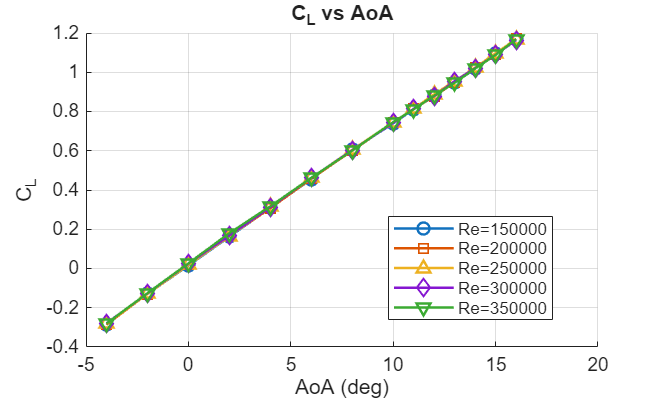

figure(3); legend(legendStrings, 'Location','best');